# FRA333-Homework 1 Solution

notation

A_T_B       =    Transformation matrix from {A} to {B} (${}^{A}_{B}T$)

A_P_Obj    =    Position of Obj's {origin} w/ respect to {A} (${}^{A} P_{Obj} $)

J_1            =    Joint 1

## Solution-1.

### **1.a. **

#### Finding transformation ${}^{Cam}_{Hand}T
$ by:

### 
$${}^{Cam}_{Hand}T = {}^{Cam}_{J1}T \times {}^{J1}_{J2}T \times {}^{J2}_{Wrist}T \times {}^{Wrist}_{Hand}T $$


syms H0 H1 H2 L1 L2 L3
syms c_theta c_alpha s_theta s_alpha
syms x_obj y_obj z_obj
Cam_T_J1 = [1 0 0  0;
            0 1 0  L1;
            0 0 1 -H1;
            0 0 0  1]

$$Cam\_T\_J1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 1 & -H_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Rz_theta = [c_theta -s_theta 0;
            s_theta c_theta  0;
            0       0        1];

Rx_m90= [1 0 0;
         0 0 -(-1);
         0 -1 0];

Rz_alpha = [c_alpha -s_alpha 0;
            s_alpha c_alpha  0;
            0       0        1];
J1_R_J2 = Rz_theta * Rx_m90 * Rz_alpha;
J1_D_J2 = [0; 0; -H2];
J1_T_J2 = [J1_R_J2 J1_D_J2;
            0 0 0 1]

$$J1\_T\_J2 = \left(\begin{array}{cccc} c_{\alpha }\,c_{\theta } & -c_{\theta }\,s_{\alpha } & -s_{\theta } & 0\\ c_{\alpha }\,s_{\theta } & -s_{\alpha }\,s_{\theta } & c_{\theta } & 0\\ -s_{\alpha } & -c_{\alpha } & 0 & -H_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

J2_T_Wrist = [1 0 0 L2;
              0 1 0  0;
              0 0 1  0;
              0 0 0  1]

$$J2\_T\_Wrist = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Cam_T_Wrist = (Cam_T_J1 * J1_T_J2) * J2_T_Wrist

$$Cam\_T\_Wrist = \left(\begin{array}{cccc} c_{\alpha }\,c_{\theta } & -c_{\theta }\,s_{\alpha } & -s_{\theta } & L_{2}\,c_{\alpha }\,c_{\theta }\\ c_{\alpha }\,s_{\theta } & -s_{\alpha }\,s_{\theta } & c_{\theta } & L_{1}+L_{2}\,c_{\alpha }\,s_{\theta }\\ -s_{\alpha } & -c_{\alpha } & 0 & -H_{1}-H_{2}-L_{2}\,s_{\alpha }\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Wrist_T_Hand = [rotx(90) [L3;0;0]; 0 0 0 1]

$$Wrist\_T\_Hand = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**So **${}^{Cam}_{Hand}T $** is**

Cam_T_Hand = Cam_T_Wrist*Wrist_T_Hand

$$Cam\_T\_Hand = \left(\begin{array}{cccc} c_{\alpha }\,c_{\theta } & -s_{\theta } & c_{\theta }\,s_{\alpha } & L_{2}\,c_{\alpha }\,c_{\theta }+L_{3}\,c_{\alpha }\,c_{\theta }\\ c_{\alpha }\,s_{\theta } & c_{\theta } & s_{\alpha }\,s_{\theta } & L_{1}+L_{2}\,c_{\alpha }\,s_{\theta }+L_{3}\,c_{\alpha }\,s_{\theta }\\ -s_{\alpha } & 0 & c_{\alpha } & -H_{1}-H_{2}-L_{2}\,s_{\alpha }-L_{3}\,s_{\alpha }\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### -----------------------------------------------------------------------------------------------------------------------

### ****สำหรับข้อ 1.b และ 1.cเนื่องจากหลายคนอาจมอง *$\Delta P
$* ไม่เหมือนกันจึงขอเเยกการหาออกมาเป็น 2 version ซึ่งทั้ง 2 วิธี vector ที่เป็นคำตอบที่ได้จะไม่เท่ากัน เเต่**ขนาดของ vector ทีได้จาก 2 วิธีนั้นเท่ากัน *

### 1.b.

Given ${}^{Cam}P_{Obj}$ as

Cam_P_Obj = [x_obj; y_obj; z_obj]

$$Cam\_P\_Obj = \left(\begin{array}{c} x_{\mathrm{obj}}\\ y_{\mathrm{obj}}\\ z_{\mathrm{obj}} \end{array}\right)$$

Ver.1$\Delta P
$ define as

#### 
$$\Delta P = {}^{Cam}P_{Obj} - {}^{Cam}P_{Hand} $$


**and**

Cam_P_Hand = Cam_T_Hand*[0 0 0 1]';
Cam_P_Hand=Cam_P_Hand(1:3)

$$Cam\_P\_Hand = \left(\begin{array}{c} L_{2}\,c_{\alpha }\,c_{\theta }+L_{3}\,c_{\alpha }\,c_{\theta }\\ L_{1}+L_{2}\,c_{\alpha }\,s_{\theta }+L_{3}\,c_{\alpha }\,s_{\theta }\\ -H_{1}-H_{2}-L_{2}\,s_{\alpha }-L_{3}\,s_{\alpha } \end{array}\right)$$

#### **Then **${}^{Cam}P_{Obj} - {}^{Cam}P_{Hand} $ is

dP = Cam_P_Obj - Cam_P_Hand

$$dP = \left(\begin{array}{c} x_{\mathrm{obj}}-L_{2}\,c_{\alpha }\,c_{\theta }-L_{3}\,c_{\alpha }\,c_{\theta }\\ y_{\mathrm{obj}}-L_{1}-L_{2}\,c_{\alpha }\,s_{\theta }-L_{3}\,c_{\alpha }\,s_{\theta }\\ H_{1}+H_{2}+z_{\mathrm{obj}}+L_{2}\,s_{\alpha }+L_{3}\,s_{\alpha } \end{array}\right)$$

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

Ver.2$\Delta P
$ define as

#### 
$$\Delta P = {}^{Hand}P_{Obj} $$


#### 
$${}^{Cam}P_{Obj}   ={}^{Cam}_{Hand}T \times {}^{Hand}P_{Obj} $$


#### 
$${}^{Cam}_{Hand}T^{-1}\times{}^{Cam}P_{Obj}   = {}^{Hand}P_{Obj} $$


inv_T = inv(Cam_T_Hand)

$$inv\_T = \begin{array}{l} \left(\begin{array}{cccc} \frac{c_{\alpha }\,c_{\theta }}{\sigma_{1}} & \frac{c_{\alpha }\,s_{\theta }}{\sigma_{1}} & -\frac{s_{\alpha }}{\sigma_{3}} & -\frac{L_{2}\,{c_{\alpha }}^{2}\,{c_{\theta }}^{2}+L_{3}\,{c_{\alpha }}^{2}\,{c_{\theta }}^{2}+L_{2}\,{c_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{2}\,{c_{\theta }}^{2}\,{s_{\alpha }}^{2}+L_{3}\,{c_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{3}\,{c_{\theta }}^{2}\,{s_{\alpha }}^{2}+L_{2}\,{s_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{3}\,{s_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{1}\,c_{\alpha }\,s_{\theta }+H_{1}\,{c_{\theta }}^{2}\,s_{\alpha }+H_{2}\,{c_{\theta }}^{2}\,s_{\alpha }+H_{1}\,s_{\alpha }\,{s_{\theta }}^{2}+H_{2}\,s_{\alpha }\,{s_{\theta }}^{2}}{\sigma_{1}}\\ -\frac{s_{\theta }}{\sigma_{2}} & \frac{c_{\theta }}{\sigma_{2}} & 0 & -\frac{L_{1}\,c_{\theta }}{\sigma_{2}}\\ \frac{c_{\theta }\,s_{\alpha }}{\sigma_{1}} & \frac{s_{\alpha }\,s_{\theta }}{\sigma_{1}} & \frac{c_{\alpha }}{\sigma_{3}} & \frac{H_{1}\,c_{\alpha }\,{c_{\theta }}^{2}-L_{1}\,s_{\alpha }\,s_{\theta }+H_{2}\,c_{\alpha }\,{c_{\theta }}^{2}+H_{1}\,c_{\alpha }\,{s_{\theta }}^{2}+H_{2}\,c_{\alpha }\,{s_{\theta }}^{2}}{\sigma_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={c_{\alpha }}^{2}\,{c_{\theta }}^{2}+{c_{\alpha }}^{2}\,{s_{\theta }}^{2}+{c_{\theta }}^{2}\,{s_{\alpha }}^{2}+{s_{\alpha }}^{2}\,{s_{\theta }}^{2}\\ \sigma_{2}={c_{\theta }}^{2}+{s_{\theta }}^{2}\\ \sigma_{3}={c_{\alpha }}^{2}+{s_{\alpha }}^{2} \end{array}$$

So ${}^{Hand}P_{Obj}$ is

Hand_P_Obj = inv(Cam_T_Hand)*[Cam_P_Obj;1]

$$Hand\_P\_Obj = \begin{array}{l} \left(\begin{array}{c} \frac{c_{\alpha }\,c_{\theta }\,x_{\mathrm{obj}}}{\sigma_{1}}-\frac{s_{\alpha }\,z_{\mathrm{obj}}}{\sigma_{3}}-\frac{L_{2}\,{c_{\alpha }}^{2}\,{c_{\theta }}^{2}+L_{3}\,{c_{\alpha }}^{2}\,{c_{\theta }}^{2}+L_{2}\,{c_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{2}\,{c_{\theta }}^{2}\,{s_{\alpha }}^{2}+L_{3}\,{c_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{3}\,{c_{\theta }}^{2}\,{s_{\alpha }}^{2}+L_{2}\,{s_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{3}\,{s_{\alpha }}^{2}\,{s_{\theta }}^{2}+L_{1}\,c_{\alpha }\,s_{\theta }+H_{1}\,{c_{\theta }}^{2}\,s_{\alpha }+H_{2}\,{c_{\theta }}^{2}\,s_{\alpha }+H_{1}\,s_{\alpha }\,{s_{\theta }}^{2}+H_{2}\,s_{\alpha }\,{s_{\theta }}^{2}}{\sigma_{1}}+\frac{c_{\alpha }\,s_{\theta }\,y_{\mathrm{obj}}}{\sigma_{1}}\\ \frac{c_{\theta }\,y_{\mathrm{obj}}}{\sigma_{2}}-\frac{L_{1}\,c_{\theta }}{\sigma_{2}}-\frac{s_{\theta }\,x_{\mathrm{obj}}}{\sigma_{2}}\\ \frac{H_{1}\,c_{\alpha }\,{c_{\theta }}^{2}-L_{1}\,s_{\alpha }\,s_{\theta }+H_{2}\,c_{\alpha }\,{c_{\theta }}^{2}+H_{1}\,c_{\alpha }\,{s_{\theta }}^{2}+H_{2}\,c_{\alpha }\,{s_{\theta }}^{2}}{\sigma_{1}}+\frac{c_{\alpha }\,z_{\mathrm{obj}}}{\sigma_{3}}+\frac{c_{\theta }\,s_{\alpha }\,x_{\mathrm{obj}}}{\sigma_{1}}+\frac{s_{\alpha }\,s_{\theta }\,y_{\mathrm{obj}}}{\sigma_{1}}\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={c_{\alpha }}^{2}\,{c_{\theta }}^{2}+{c_{\alpha }}^{2}\,{s_{\theta }}^{2}+{c_{\theta }}^{2}\,{s_{\alpha }}^{2}+{s_{\alpha }}^{2}\,{s_{\theta }}^{2}\\ \sigma_{2}={c_{\theta }}^{2}+{s_{\theta }}^{2}\\ \sigma_{3}={c_{\alpha }}^{2}+{s_{\alpha }}^{2} \end{array}$$

### -----------------------------------------------------------------------------------------------------------------------

### 1.c. 

#### Subsitude the value below

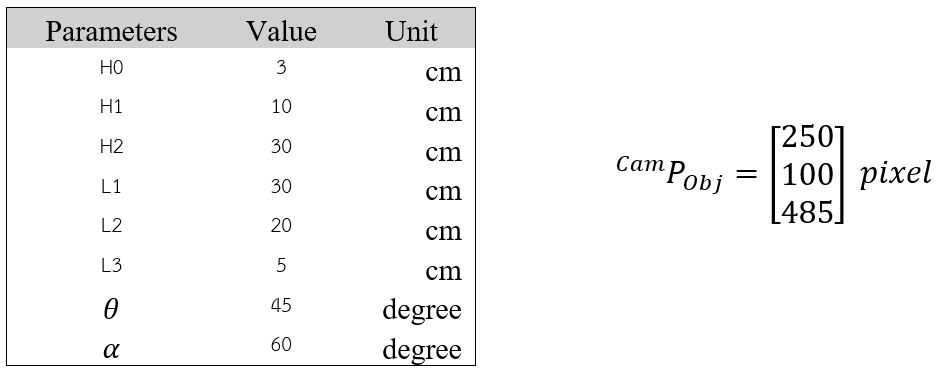

Ver.1$\Delta P
$ define as

#### 
$$\Delta P = {}^{Cam}P_{Obj} - {}^{Cam}P_{Hand} $$


**To solve 1.c. need to know **${}^{Head} P_{Obj} $ **and** ${}^{Head} P_{Hand} $

**Find **${}^{Head} P_{Obj}
$** by**

### 
$${}^{Head} P_{Obj} = {}^{Head}_{Cam} T \times{}^{Cam} P_{Obj} $$


Head_T_Hand = Cam_T_Hand;
H0 = 3;
H1 = 10;
H2 = 30;
L1 = 30;
L2 = 20;
L3 = 5;
c_theta = cos(pi/4);
c_alpha = cos(pi/3);
s_theta = sin(pi/4);
s_alpha = sin(pi/3);
x_obj = 250/50;
y_obj = 100/50;
z_obj = 485/50;


$${}^{Head}_{Cam} T=$$

$$\left\lbrack \begin{array}{cc}
{\textrm{Rot}}_y \left({30}^o \right) & {\textrm{Trans}}_z \left(-\textrm{H0}\right)\\
0\;0\;0 & 1
\end{array}\right\rbrack$$


Head_T_Cam = [roty(30) [0;0;-H0]; 0 0 0 1]

Head_T_Cam =     0.8660         0    0.5000         0
         0    1.0000         0         0
   -0.5000         0    0.8660   -3.0000
         0         0         0    1.0000


Unit cm

**Then **${}^{Head} P_{Obj} $** is**

sub_Head_P_Obj = double(Head_T_Cam*[subs(Cam_P_Obj);1]) % cm

sub_Head_P_Obj =     9.1801
    2.0000
    2.9004
    1.0000


Unit cm

**Calcualte **${}^{Head} P_{Hand} $** From 1.b. **

sub_Head_P_Hand = double([subs(Cam_P_Hand);1])

sub_Head_P_Hand =     8.8388
   38.8388
  -61.6506
    1.0000


Unit cm

#### So $\Delta P
$ is

sub_Hand_P_Obj_V1 = sub_Head_P_Obj - sub_Head_P_Hand % cm 

sub_Hand_P_Obj_V1 =     0.3413
  -36.8388
   64.5511
         0


length_V1 = sqrt(sub_Hand_P_Obj_V1(1)^2 + sub_Hand_P_Obj_V1(2)^2 + sub_Hand_P_Obj_V1(3)^2)

length_V1 = 74.3240

Unit cm

sub_Hand_P_Obj_V1_SI = double(sub_Hand_P_Obj_V1)*0.01 % m

sub_Hand_P_Obj_V1_SI =     0.0034
   -0.3684
    0.6455
         0


Unit m

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

Ver.2$\Delta P
$ define as

#### 
$$\Delta P = {}^{Hand}P_{Obj} $$


#### 
$${}^{Head}P_{Obj}   ={}^{Head}_{Hand}T \times {}^{Hand}P_{Obj} $$


#### 
$${}^{Head}_{Hand}T^{-1}\times{}^{Head}P_{Obj}   = {}^{Hand}P_{Obj} $$


#### So ${}^{Hand}P_{Obj}$ is

sub_Hand_P_Obj_V2 = inv(double(subs(Head_T_Hand)))* sub_Head_P_Obj

sub_Hand_P_Obj_V2 =   -68.8067
  -26.2903
    9.9255
    1.0000


length_V2 = sqrt(sub_Hand_P_Obj_V2(1)^2 + sub_Hand_P_Obj_V2(2)^2 + sub_Hand_P_Obj_V2(3)^2)

length_V2 = 74.3240

Unit cm

sub_Hand_P_Obj_V2_SI = sub_Hand_P_Obj_V2*0.01

sub_Hand_P_Obj_V2_SI =    -0.6881
   -0.2629
    0.0993
    0.0100


Unit m

## ==========================================================

## Solution-2.

load("FOBI_information.mat")

#### A.) Find ${}^{F0}_{F1}T$from

#### 
$${}^{F0}_{Obj}T = {}^{F0}_{F1}T \times {}^{F1}_{Obj}T$$


#### 
$${}^{F0}_{Obj}T \times {}^{F1}_{Obj}T^{-1}= {}^{F0}_{F1}T $$


So ${}^{F0}_{F1}T $ is

True_F0_T_F1 = F0_T_Obj*inv(F1_T_Obj)

True_F0_T_F1 =     1.0000   -0.0092   -0.0030   90.0000
    0.0091    0.9999   -0.0092 -180.0000
    0.0030    0.0091    1.0000   20.0000
         0         0         0    1.0000


#### Conclusion: FOBI_1 is Fine.

#### B.) Find ${}^{F1}_{F2}T$from

#### 
$${}^{F0}_{Obj}T = {}^{F0}_{F1}T \times {}^{F1}_{F2}T\times {}^{F2}_{Obj}T$$


#### 
$${}^{F0}_{F1}T^{-1} \times{}^{F0}_{Obj}T \times {}^{F2}_{Obj}T^{-1}=  {}^{F1}_{F2}T$$


So ${}^{F1}_{F2}T $ is

True_F1_T_F2 = inv(F0_T_F1) * F0_T_Obj * inv(F2_T_Obj)

True_F1_T_F2 =     1.0000   -0.0091    0.0031   31.2801
    0.0091    1.0000    0.0030  100.2319
   -0.0031   -0.0030    1.0000   -1.1332
         0         0         0    1.0000


#### Conclusion: FOBI_2 is Corrupt.

#### C.) Find ${}^{F3}_{F0}T$from

#### 
$${}^{F0}_{Obj}T = {}^{F0}_{F3}T \times {}^{F3}_{Obj}T$$


#### 
$${}^{F0}_{Obj}T\times {}^{F3}_{Obj}T^{-1} = {}^{F0}_{F3}T $$


So ${}^{F3}_{F0}T$ is

True_F0_T_F3 = F0_T_Obj * inv(F3_T_Obj)

True_F0_T_F3 =     0.9999    0.0137    0.0000   70.0000
   -0.0137    0.9999    0.0000  230.0000
    0.0000    0.0000    1.0000   10.0000
         0         0         0    1.0000


And

#### 
$${}^{F3}_{F0}T = {}^{F0}_{F3}T^{-1}$$


True_F3_T_F0 = inv(True_F0_T_F3)

True_F3_T_F0 =     0.9999   -0.0137   -0.0000  -66.8407
    0.0137    0.9999   -0.0000 -230.9379
   -0.0000   -0.0000    1.0000  -10.0000
         0         0         0    1.0000


#### Conclusion: FOBI_3 is Corrupt.